clear; close all;

% Permissivity
eps0 = 8.854187817e-12;

% Grid & domain
Nx = 50; Ny = 50; % number of grid points in each direction
Lx = 100.0; Ly = 100.0; Lz = 1; % grid dimensions (meters)
                                 % Lz is approximate as the z component of
                                 % each plate is actually defined elsewhere
dx = Lx/Nx; dy = Ly/Ny; % spacing of mesh points
xl = linspace(0, Lx, Nx); % used for visualization of the geometries
yl = linspace(0, Ly, Ny); % xl and yl effectively form the x and y axes (and provide scaling)
zlb = zeros(Nx, Ny); % zlt holds the z component at mesh point (x, y) for the top surface
zlt = zeros(Nx, Ny); % zlb holds the z component at mesh point (x, y) for the bottom surface

% Here is where we define the plate geometry. I encourage you to play
% around with it to see the different visualizations! Tip: If you are
% trying to make a specific shape but it isn't working, this may be because the x and y values 
% don't have a wide enough "span" to be seen. You can try
% increasing the plate length, dividing the x or y values in your equation
% to make them smaller, or increasing top_valid_num and bot_valid_num.

% Here are a few geometries we have pre-defined for you! If you would like
% to visualize them, you can just write the function name in the z_bot or
% z_top equation as shown below. 
z_bot_flat = @(x, y) 0; % function that describes z of top and bottom plates
z_top_flat = @(x, y) Lz;

z_bot_wave1 = @(x, y) sin(x) + cos(y);
z_top_wave1 = @(x, y) sin(x) + cos(y) + Lz;

z_bot_wave2 = @(x, y) - x^1.5/100 + y^2/300;
z_top_wave2 = @(x, y) sin(x/5)*2 - cos(y/3) + Lz;

z_bot_wave3 = @(x, y) sin(x/5+2);
z_top_wave3 = @(x, y) cos(x/10) + Lz;

xy_circle = @(x, y) (x-Lx/2)^2 + (y-Ly/2)^2;
xy_triange = @(x, y) 15*x +10*y;

n_bumps = 30; % number of bumps for following surfaces
z_bot_bump = @(x, y) sin(x/100*pi*n_bumps)/2;
z_top_bump = @(x, y) sin(x/100*pi*n_bumps)/2 + Lz;

% Here is where the geometry that is actually plotted is defined
z_bot = @(x, y) z_bot_flat(x, y); % function that describes z of top and bottom plates
z_top = @(x, y) z_top_flat(x, y); 
top_valid_num = 10000; % we define the "allowed xy region" for the surface through the equation xy_top <= top_valid_num
xy_top = @(x, y) xy_circle(x, y); % for example, xy_top = (x-Lx/2)^2 + (y-Ly/2)^2 <= r^2 = top_valid_num is the equation of a circle
bot_valid_num = 10000;
xy_bot= @(x, y) xy_circle(x, y);
delt_V = 10; % Voltage across the plates

% Initalizing the voltage at each mesh point
V = transpose(zeros(1, Nx*2*Ny)); % there are Nx*Ny mesh points on each surface, for a total of 2*Nx*Ny mesh points
V(Nx*Ny+1:Nx*Ny*2) = delt_V; % The first Nx*Ny mesh points are those on the bottom plate, while the second Nx*Ny mesh points (those in the range Nx*Ny + 1 to 2*Nx*Ny)
                            % are those on the top. These top mesh points
                            % will all be at 10 V, as this is the boundary
                            % condition we have chosen to enforce. Feel
                            % free to play around with the voltage and see
                            % how it infulences the results!

% Initalizing the r (position) matrix to contain the position vector at each mesh point
r = zeros(Nx*Ny*2, 3); % Here, the rows represent mesh point index, and the columns represent the x, y, and z components of the mesh point's position, respectively 
                        % Mesh point indexing is as follows: index = x*Nx + y for the bottom plate and index = x*Nx + y + Nx*Ny for the top
for i = 1:Nx
    for j = 1:Ny
        x_coord = (i-0.5)*dx; % x and y coordinates
        y_coord = (j-0.5)*dy;
        valid_top_coord = xy_top(x_coord, y_coord); % plug xy coordinate into the equation for the top and bottom surfaces to check if this point is "allowed"
        valid_bot_coord = xy_bot(x_coord, y_coord);

        % Top plate:
        if (valid_top_coord <= top_valid_num) % for a circle, x^2 + y^2 <= r^2 - this is what this checks
            zlt(i, j) = z_top(x_coord, y_coord); % set the z coordinate of each mesh point for visualization
            r((i-1)*Nx + j + Nx*Ny, :) = [x_coord, y_coord, z_top(i, j)]; % setting the coordinate of each mesh point inside the position matrix
        else  % if the mesh point falls outside of the allowed xy region, assign it NaN to have it be ignored by the rest of the program
            zlt(i, j) = NaN;
            r((i-1)*Nx + j + Nx*Ny, :) = [NaN, NaN, NaN];
        end

        % Bottom plate:
        if (valid_bot_coord <= bot_valid_num) % Checking if the coordinates are valid for the bottom plate
            zlb(i, j) = z_bot(x_coord, y_coord); % setting the z coordinate of each mesh point on the bottom plate for visualization
            r((i-1)*Ny + j, :) = [x_coord, y_coord, z_bot(i, j)]; % setting position matrix at the bottom plate mesh point
        else  % if the mesh point falls outside of the allowed xy region, set to NaN
            zlb(i, j) = NaN;
            r((i-1)*Ny + j, :) = [NaN, NaN, NaN];
        end
    end
end

% G is the influence matrix used to relate V, the voltage, to rho, charge
% density, at each point
% Gij = Aj/(4 pi epsilon |ri - rj|), ri is vector (from position matrix r)
% to center of patch i, rj is vector to center of patch j

% there are Nx*Ny patches on each plate, so 2*Nx*Ny patches in total
% each patch influences every other patch, so G will be a 2*Nx*Ny by
% 2*Nx*Ny matrix
G = zeros(Nx*Ny*2, Nx*Ny*2); 

for i = 1:(Nx*Ny*2) % going through all of the mesh points to find their charge density
    % Calculating the area of patch i
    if i <= Nx*Ny % Checking if i is on the top or bottom plate
        min_ind = 1; % If on the bottom plate, the edges of the allowed region are index 1 and index Nx*Ny
        max_ind = Nx*Ny;
    else
        min_ind = Nx*Ny+1; % If on the top plate, the edges of the allowed region are index Nx*Ny+1 and 2*Nx*Ny
        max_ind = 2*Nx*Ny;
    end

    if i - Nx >= min_ind % Checking if the patch to the left is part of the surface
        if ~isnan(r(i-Nx))
            length_left = norm(r(i-Nx)-r(i)); % if patch to the left is part of surface, find the distance to it
                                            % this is an approximation of
                                            % the side length of the patch
        else
            length_left = 0; % If the patch to the left is not part of the surface, ignore. 
                            % We will approximate this side length by just
                            % the length_right instead of the average
        end
    else
        length_left = 0;
    end
    if i + Nx <= max_ind % Checking the right
        if ~isnan(r(i+Nx))
            length_right = norm(r(i+Nx)-r(i));
        else
            length_right = 0;
        end
    else
        length_right = 0;
    end
    if i - 1 >= min_ind
        if ~isnan(r(i-1))
            length_bwd = norm(r(i-1)-r(i));
        else
            length_bwd = 0;
        end
    else
        length_bwd = 0;
    end
    if i + 1 <= max_ind
        if ~isnan(r(i+1))
            length_fwd = norm(r(i+1)-r(i));
        else
            length_fwd = 0;
        end
    else
        length_fwd = 0;
    end

    if length_fwd == 0 || length_bwd == 0
        len1 = length_fwd + length_bwd;
    else
        len1 = (length_fwd + length_bwd)/2;
    end
    if length_left == 0 || length_right == 0
        len2 = length_left + length_right;
    else
        len2 = (length_left + length_right)/2;
    end
    
    % Checking if any of the lengths are zero. This happens in some cirular
    % geometries, where at the edges only one direction has a non-zero
    % length
    if len1 == 0
        A_patch = len2^2;
    elseif len2 == 0
            A_patch = len1^2;
    else
        A_patch = len1*len2;
    end

    for j = 1:(Nx*Ny*2) % going through all of the mesh points again to find how they interact with point i
        if ~anynan(r(i, :)) && ~anynan(r(j, :)) % checking that the position has not been set to NaN. 
                                                % A NaN value indicates that the mesh point does not lie on the surface
            deltR = r(i, :) - r(j, :); % deltR = ri - rj
            if (i ~= j) % if i and j are the same point, deltR = 0 and the integral cannot be approximated by this formula
                G(i, j) = A_patch/norm(deltR)/ (4 * pi * eps0); % regular Gij formula
            else
                G(i, j) = dy/(pi * eps0) * log(1+ 2^0.5); % self term approximation for square patches, gives the approximate infulence of a patch on itself
            end
        end
    end
end

% We know that G * rho = V, so we can calculate rho as the inverse of G times V
rho = V \ G;
rho_top = rho(Ny*Nx+1:2*Ny*Nx); % Charge densities on top plate
rho_bot = rho(1:Ny*Nx); % Charge densities on bottom plate

% Total charge on a plate is the sum of charge density on each patch times area of patch
Q_tot_top = abs(sum(rho_top))*A_patch; % equal patch sizes, so we can "bring out" the A_patch multiplication
C_top = Q_tot_top/delt_V; % Capacitance is Q/V
Q_tot_bot = abs(sum(rho_bot)) * A_patch; % We take the absolute value because one plate will have positive charge and the other will have negative,
C_bot = Q_tot_bot/delt_V;                % taking the absolute value makes the charge density comparision simpler

C = (C_bot + C_top)/2 % averaging the capacitance calculated from the top and bottom plates

C = 1.0578e+11

Percent_Error_Estimate = abs(Q_tot_top-Q_tot_bot)/(Q_tot_top+Q_tot_bot)*200 % Theoretically, the total charge on the top and bottom should be the same

Percent_Error_Estimate = 1.6730

                                                                            % We are using their difference when calculated numerically as an apporimate error heuristic
C_ana = Lx*Ly/Lz*eps0 % Capacitance of a parallel plate capacitor assuming plates are long enough for edge effects to be negligible. We calulate this as a reference

C_ana = 8.8542e-08

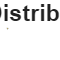


% Initalize the charge density colormap
Colour_top = zeros(Nx, Ny);
Colour_bot = zeros(Nx, Ny);

for i = 1:(Nx)
    for j = 1:(Nx)
        % Colour at point x, y will correspond to the charge density at the same point
        Colour_top(i, j) = abs(rho_top((i-1)*Nx + j));
        Colour_bot(i, j) = abs(rho_bot((i-1)*Nx + j)); 
    end
end

% Plot the surfaces with the charge density
figure;
surf(xl, yl, zlb, Colour_bot, 'EdgeColor','none');
hold on;
surf(xl, yl, zlt, Colour_top, 'EdgeColor','none');
colorbar;
xlabel('x');
ylabel('y');
zlabel('z');
title('Charge Distribution');
hold off;